# Skin Lesion Classification via CNN Transfer Learning

Last updated: October 7, 2021

#### Load dataset

dataLocation = "Dataset/ISIC_2019_Training_Input"

dataLocation = "Dataset/ISIC_2019_Training_Input"

labelsLocation = "Dataset/groundtruth_categorical.csv"

labelsLocation = "Dataset/groundtruth_categorical.csv"

Create a datastore for the raw images

image_datastore = imageDatastore(dataLocation);
num_images = length(image_datastore.Files);

Import ground truth labels

groundtruth = readtable(labelsLocation);
image_datastore.Labels = categorical(groundtruth.category(1:num_images));
labelCounts = countEachLabel(image_datastore)

labelCounts = 8×2 table
             Label             Count
    _______________________    _____

    Actinic keratosis            867
    Basal cell carcinoma        3323
    Benign keratosis            2624
    Dermatofibroma               239
    Melanocytic nevus          12875
    Melanoma                    4522
    Squamous cell carcinoma      628
    Vascular lesion              253


minCategoryImageCount = min(labelCounts.Count);

Display some images with their labels

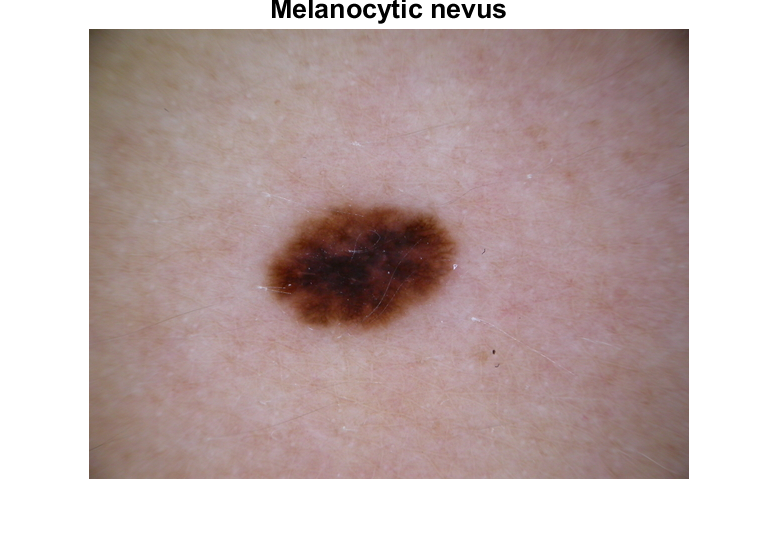

sample_idx = 11436;
imshow(readimage(image_datastore, sample_idx));
title(image_datastore.Labels(sample_idx), 'FontSize', 20);

#### Split dataset into training set, validation set, and test set.

[trainImds, valImds] = splitEachLabel(image_datastore, 0.8, 'randomized');

### Balance training set by oversampling underrepresented classes

trainingLabelCounts = countEachLabel(trainImds);
targetLabelCount = floor(5000*0.8);
balTrainImds = oversampleDataset(trainImds, targetLabelCount);
labelCounts = countEachLabel(balTrainImds)

labelCounts = 8×2 table
             Label             Count
    _______________________    _____

    Actinic keratosis           4858
    Basal cell carcinoma        7974
    Benign keratosis            6297
    Dermatofibroma              4202
    Melanocytic nevus          10300
    Melanoma                   10854
    Squamous cell carcinoma     4518
    Vascular lesion             4242


#### Augment images and Resize images to work with GoogLeNet

augmenter = imageDataAugmenter("RandXReflection", true, "RandYReflection", true, "RandRotation", [-180 180]);
trainds = augmentedImageDatastore([224,224], balTrainImds,"DataAugmentation",augmenter);
minibatch = preview(trainds);
imshow(imtile(minibatch.input));

valds = augmentedImageDatastore([224,224], valImds);

### Import and modify pretrained Neural Network

net = googlenet;
lgraph = layerGraph(net);

newFc = fullyConnectedLayer(numel(labelCounts.Label),"Name","new_fc");
lgraph = replaceLayer(lgraph,"loss3-classifier",newFc);

#### Implement weighted cross-entropy loss to address imbalanced dataset

classWeights = 1000*ones(1,numel(labelCounts.Label)) ./ labelCounts.Count'

classWeights =     0.2058    0.1254    0.1588    0.2380    0.0971    0.0921    0.2213    0.2357



newOut = classificationLayer("Name","new_out", "ClassWeights", classWeights, "Classes", labelCounts.Label);
lgraph = replaceLayer(lgraph,"output",newOut);

### Set training options

Stochastic Gradient Descent with Momentum

Learning rate = 0.001

options = trainingOptions("sgdm","InitialLearnRate", 0.001,'MiniBatchSize',128/2, 'MaxEpochs', 400,'Plots','training-progress')

options =   TrainingOptionsSGDM with properties:

                        Momentum: 0.9000
                InitialLearnRate: 1.0000e-03
               LearnRateSchedule: 'none'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                       MaxEpochs: 400
                   MiniBatchSize: 64
                         Verbose: 1
                VerboseFrequency: 50
                  ValidationData: []
             ValidationFrequency: 50
              ValidationPatience: Inf
                         Shuffle: 'once'
                  CheckpointPath: ''
            ExecutionEnvironment: 'auto'
                      WorkerLoad: []
                       OutputFcn: []
                           Plots: 'training-progress'
                  SequenceL

### Train the neural network

Training on single GPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:07 |       12.50% |       0.7204 |          0.0010 |
|       1 |          50 |       00:01:01 |       20.31% |       0.2727 |          0.0010 |
|       1 |         100 |       00:01:56 |       28.12% |       0.2640 |          0.0010 |
|       1 |         150 |       00:02:52 |       35.94% |       0.2745 |          0.0010 |
|       1 |         200 |       00:03:47 |       43.75% |       0.2425 |          0.0010 |
|       1 |         250 |       00:04:42 |       35.94% |       0.2490 |          0.0010 |
|       1 |         300 |  

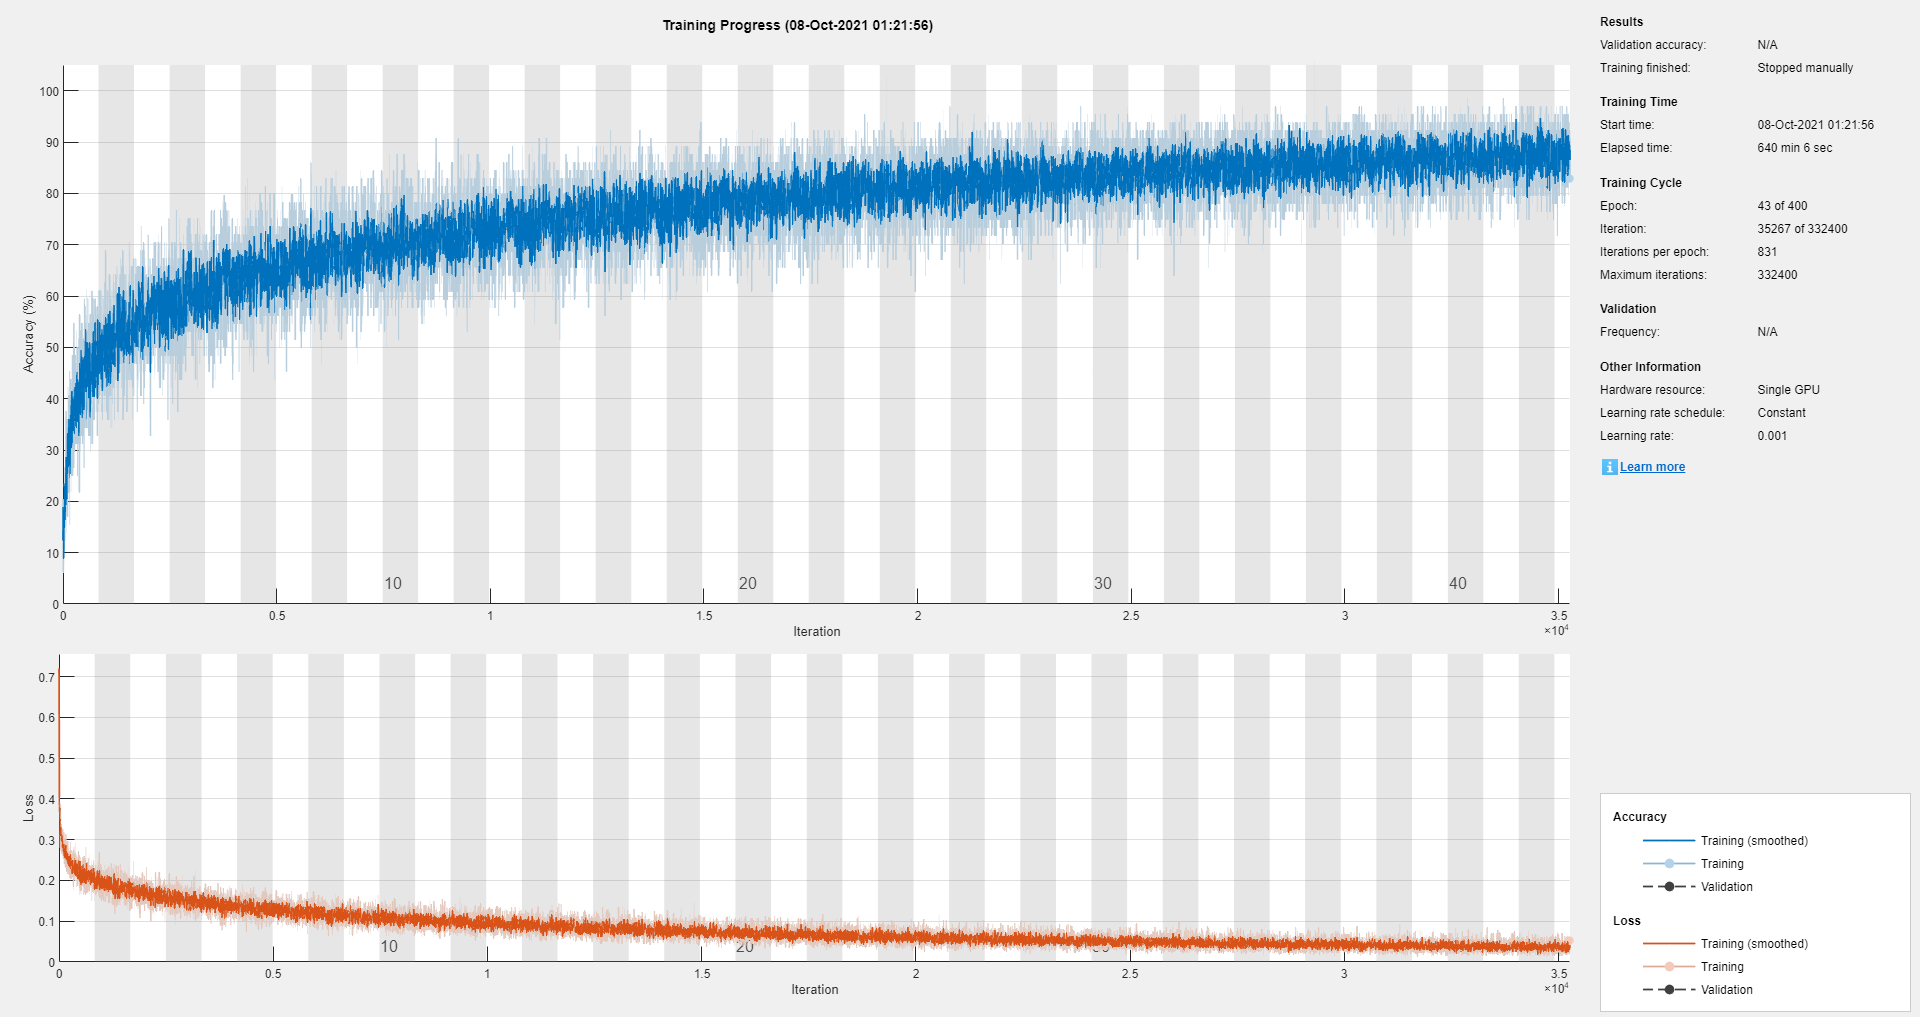

lesionNet = trainNetwork(trainds, lgraph, options);

Save trained model to device

save lesionNet_prev.mat lesionNet;

#### Evaluate network on Validation set

preds = classify(lesionNet, valds);
valTrue = valImds.Labels;
valAccuracy = nnz(preds == valTrue)/numel(preds)

valAccuracy = 0.7531

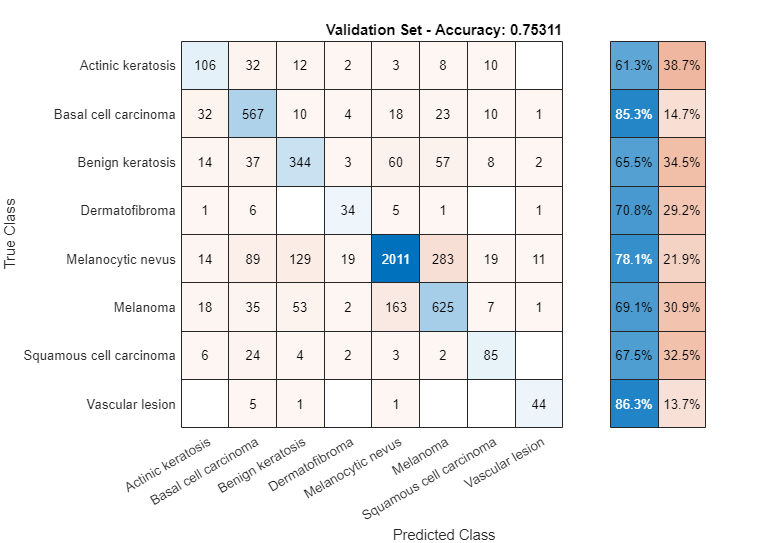

confusionchart(valTrue, preds, 'RowSummary','row-normalized', 'Title',"Validation Set - Accuracy: " + string(valAccuracy));

### Visualize failed predictions

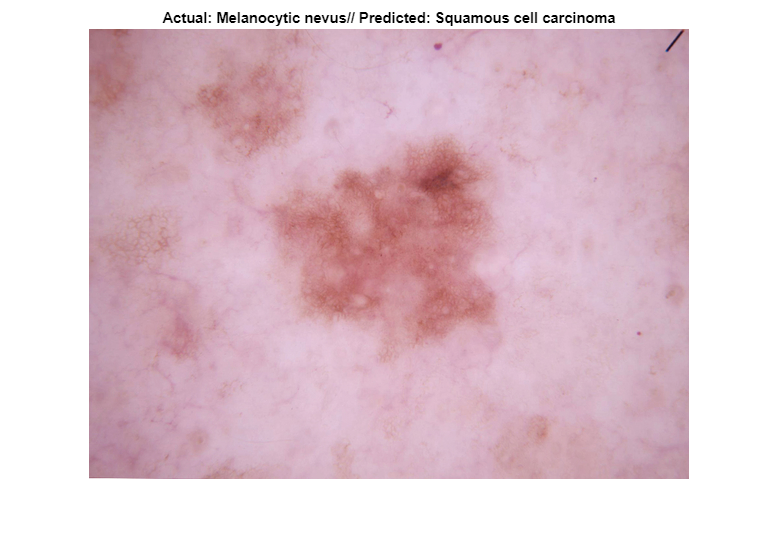

failedPredictions = find(preds~=valTrue);
num_fail = numel(failedPredictions);
failedSample = 414;
if ~isempty(failedPredictions)
    imshow(readimage(valImds,failedPredictions(failedSample)), 'InitialMagnification', 100);
    title("Actual: " + string(valTrue(failedPredictions(failedSample))) + "// Predicted: " + string(preds(failedPredictions(failedSample))))
end

### Visualize correct predictions

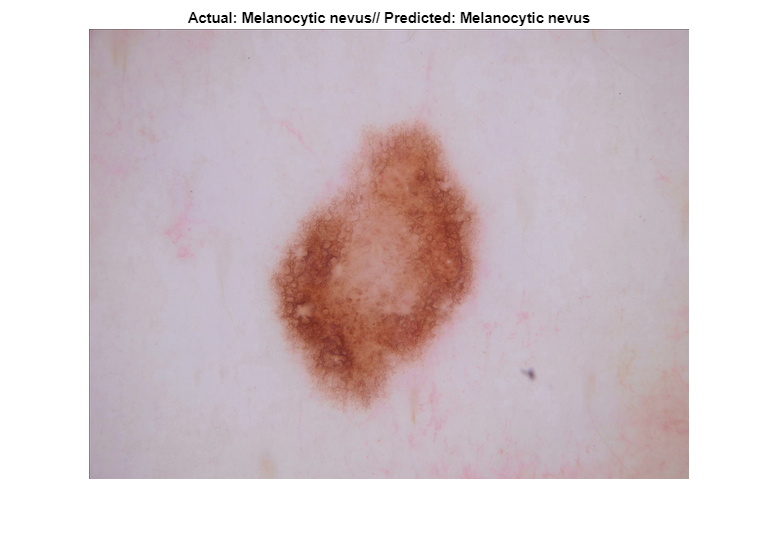

correctPredictions = find(preds==valTrue);
num_correct = numel(correctPredictions);
correctSample = 643;
if ~isempty(correctPredictions)
    imshow(readimage(valImds,correctPredictions(correctSample)), 'InitialMagnification', 100);
    title("Actual: " + string(valTrue(correctPredictions(correctSample))) + "// Predicted: " + string(preds(correctPredictions(correctSample))))
end